# **Project 1**

BENG280A FQ23 Group#23

Due: 11/8/2023

## Set up a phantom to scan

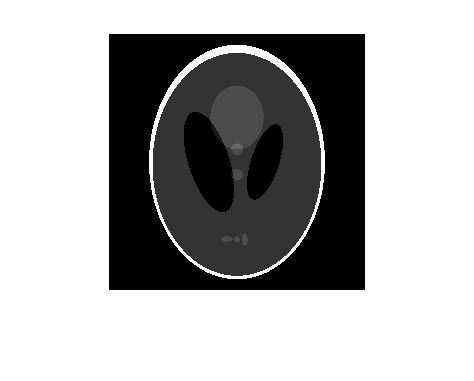

p = phantom(256);
imshow(p)

## Set up scan type

scan_type = "";

"parallel"

ans = "parallel"

if scan_type == "parallel"
    scan = @(x) radon(x,0:1:180); % default angle 0:1:180
    iscan = @(x) iradon(x, 0:1:180);
else
    scan = @(x) fanbeam(x, 250); % default distance 250
    iscan = @(x) ifanbeam(x, 250);
end

## Scan phantom

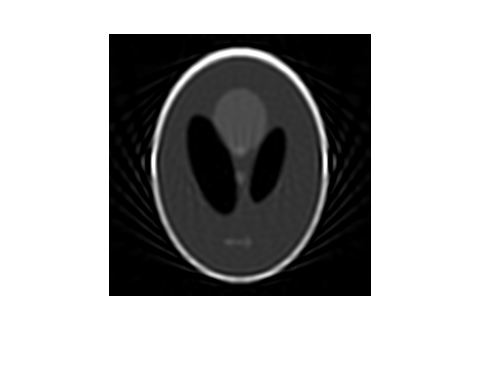

sinogram = scan(p);
imshow(iscan(sinogram))